# Understanding $\nabla \cdot(\phi\vec{u})$ and$\vec{u}\cdot\nabla\phi$

#### By: Arnaldo Rodriguez-Gonzalez

- This Live Script lets you determine the value of $\nabla \cdot(\phi\vec{u})$ and$\vec{u}\cdot\nabla\phi$ given some 2-D vector field $\vec{u}$ and a 2-D differentiable scalar field $\phi$. 

- The expressions $\nabla \cdot(\phi\vec{u})$ and $\vec{u}\cdot\nabla\phi$ show up often in fluid dynamics and vector calculus; for example, $\vec{u}\cdot\nabla\phi$ relates Eulerian and Lagrangian descriptions of a quantity $\phi$ flowing in a velocity field $\vec{u}$ through the equation $\frac{D\phi}{Dt} = \frac{\partial\phi}{\partial t} + \vec{u}\cdot\nabla\phi$, where $\frac{D\phi}{Dt}$ is the Lagrangian derivative of $\phi$ and $\frac{\partial\phi}{\partial t}$ is the Eulerian derivative of $\phi$. 

- $\nabla \cdot(\phi\vec{u})$ shows up often in the construction of transport theorems and differential conservation laws; given some scalar quantity $\phi$ flowing in a velocity field $\vec{u}$ such that, over the region $\Omega$ where $\phi$ is defined, $\frac{d\int_\Omega\phi}{dt} = 0$, then $\phi$ (under suitable differentiability constraints) satisfies the equation $\frac{\partial\phi}{\partial t} + \nabla \cdot (\phi\vec{u}) = 0$.

- Type the components of $\vec{u}$ and $\phi$ in below to see plots of each individual quantity, as well as a plot of the resulting scalar fields $\vec{u}\cdot\nabla\phi$ and $\nabla \cdot(\phi\vec{u})$.

Type in the components of the vector field $\vec{u}$ in the x- and y-directions in the box below as functions of x and y.

syms x y
xv=2*x;
yv=-2*y^2;

Now type in the scalar function $\phi$ into the box below as a function of x and y.

phi=4*x + 5*cos(y);
phix = diff(phi,x);
phiy = diff(phi,y);
divuphi = diff(xv*phi,x) + diff(yv*phi,y);
udotgradphi = xv*phix + yv*phiy;
xvn = matlabFunction(xv, 'vars', [x y]);
yvn = matlabFunction(yv,'vars', [x y]);
[xg,yg] = meshgrid([-5:.25:5]);

The plot below is showing two things; the contours where the value of $\phi$ stays the same, and the vector field $\vec{u}$ described by the components you inputted.

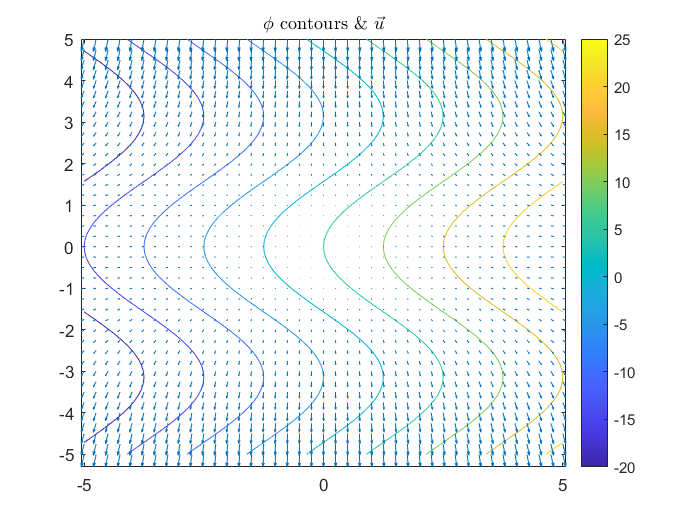

fcontour(phi)
colorbar
hold on
quiver(xg,yg,xvn(xg,yg),yvn(xg,yg))
hold off
title('$\phi$ contours $\&\ \vec{u}$','Interpreter','latex');

Below you can see the value of $\nabla \cdot(\phi\vec{u})$.

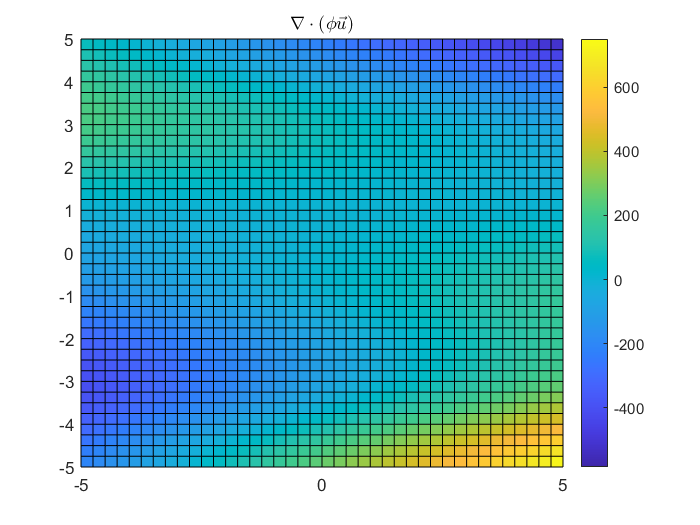

figure
z2 = matlabFunction(divuphi,'vars',[x y]);
surface(xg,yg,z2(xg,yg))
colorbar
title('$\nabla \cdot(\phi\vec{u})$','Interpreter','latex');

Below you can see the value of $\vec{u}\cdot\nabla\phi$.

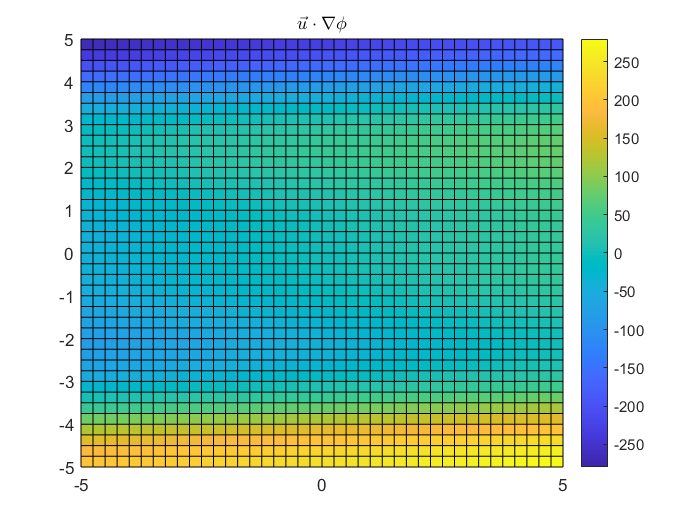

figure
z = matlabFunction(udotgradphi,'vars',[x y]);
surface(xg,yg,z(xg,yg))
colorbar
title('$\vec{u}\cdot\nabla\phi$','Interpreter','latex');

## Activities

- Generate plots for 5 different choices of $\vec{u}$ and $\phi$. Note, qualitatively, the differences between the plots of $\nabla \cdot(\phi\vec{u})$ and $\vec{u}\cdot\nabla\phi$. you generate.

- Find non-zero values for $\vec{u}$ and $\phi$ such that $\vec{u}\cdot\nabla\phi$ is zero everywhere.

- Find non-zero values for $\vec{u}$ and $\phi$ such that $\nabla \cdot(\phi\vec{u})$ is zero everywhere.

- Can you find non-zero values for $\vec{u}$ and $\phi$ such that $\nabla \cdot(\phi\vec{u})$ is zero everywhere, but $\vec{u}\cdot\nabla\phi$ is not? If so, provide an example; if not, state your reasoning.

- Can you find non-zero values for $\vec{u}$ and $\phi$ such that $\vec{u}\cdot\nabla\phi$ is zero everywhere, but $\nabla \cdot(\phi\vec{u})$ is not? If so, provide an example; if not, state your reasoning.

- Find 3 values of $\vec{u}$ and $\phi$ such that $\nabla \cdot(\phi\vec{u})$ is equal to $\vec{u}\cdot\nabla\phi$. 

- Under what mathematical circumstances would $\nabla \cdot(\phi\vec{u})$ be equal to $\vec{u}\cdot\nabla\phi$? In the context of fluid dynamics, under what physical circumstances would this equality be satisfied?